# Activity 8 Part 1: Perceptron

#### Part I: Loading the dataset 

%%loading the dataset
clear;close;
DataSetPath = "c:\Users\Johnenn\OneDrive\Documents\MATLAB\archive\fruits-360_dataset\fruits-360";
cornFolder = fullfile(DataSetPath,'Training', 'Corn');
strawberryFolder = fullfile(DataSetPath, 'Training', 'Strawberry');

%storing the images
cornImages = imageDatastore(cornFolder);
strawberryImages = imageDatastore(strawberryFolder);

numCornImages = numel(cornImages.Files(1:100));
numStrawberryImages = numel(strawberryImages.Files(1:100));

#### Part II : Extracting Features (Eccentricity and Greenness)

Extracting feature 1: Eccentricity 

Feature1 = zeros(numCornImages+numStrawberryImages, 1);
%For corn images
for i = 1:numCornImages
    Feature1(i) = feature1(cornImages, i);
end
%For strawberry images
for i = 1:numStrawberryImages
    Feature1(i+100) = feature1(strawberryImages,i); %appending the values
end

Extracting feature 2: Greenness

Feature2 = zeros(numCornImages+numStrawberryImages, 1);
%For corn images
for i = 1:numCornImages
    Feature2(i) = feature2(cornImages,i);
end
%For strawberry images
for i = 1:numStrawberryImages
    Feature2(i+100) = feature2(strawberryImages, i); %appending the values
end

#### Part III: Perceptron Weight Change Rule

For each sample i, 

1.Include a bias input (Feature0 = 1) in all sample inputs. Let d be the class label for the features: 

                            d(1:50) = 1 (for corn)

                            d(51:100) = -1 (for strawberry)

%Include a constant bias 
%Bias = 1
Feature0 = ones(200,1);

%Labeling 
d = zeros(200,1);
d(1:100) = 1;
d(101:200) = -1;

%Combining all data in one array
FEATURES = [Feature0, Feature1, Feature2];

2. Initialize the weights to some random number. 

Here, we'll use the rand(n,m) function to create an array of random numbers of size n-by-m. 

%weights
w = rand(3,1)*0.01;

3. Calculate the perceptron output as in Steps 1 and 2. We will use the step function as the thresholding function:

where a is the sum of the product of the features and the synaptic weights for each sample.

4. Calculate the weight change as 

5. Update the weights as 

6. Iterate through samples. Stop when the number of iterations is reached.


eta = 0.01; %set the learning rate eta
epochs = 1e5; %set the training time 

for epoch = 1:epochs

    for i = 1:size(FEATURES,1)

        a = dot(FEATURES(i,:), w); %calculate product of features and weights

        %Thresholding 
        if a >= 0
            z = 1;
        else
            z = -1;
        end
        
        %Weight change 
        delta_w = eta*(d(i,:) - z)*FEATURES(i,:)';

        %Updating weight
        w = w + delta_w;
    end 
end

#### PART IV: Plotting the data 

Plot the data in feature space and overlay the decision line. 

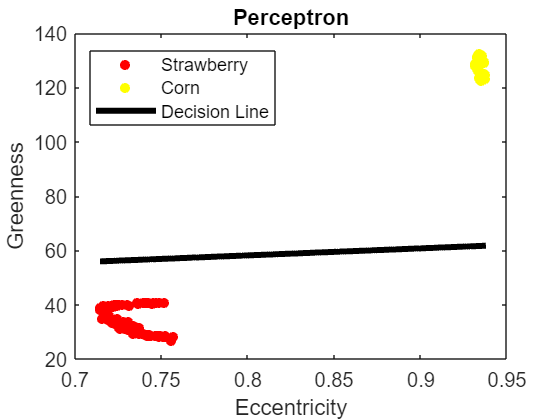

%Decision line
m = -(w(2)./w(3));
b = -(w(1)./w(3));
x = linspace(min(FEATURES(:,2)), max(FEATURES(:,2)), 200);
y = m * x + b;

%Plotting
gscatter(FEATURES(:,2), FEATURES(:,3), d(:,1), 'ry');
hold on; 
plot(x,y,'k-', 'LineWidth', 3);
hold off;
legend('Strawberry', 'Corn', 'Decision Line');
axis 'autoxy';
ylabel('Greenness');
xlabel('Eccentricity');
title('Perceptron');

#### PART V: Testing 

Test the perceptron if it can classify fruits. 

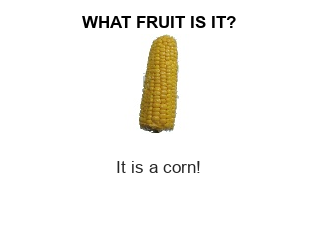

%Loading image folders for testing
cornFolderTest = fullfile(DataSetPath,'Test', 'Corn');
strawberryFolderTest = fullfile(DataSetPath, 'Test', 'Strawberry');

%storing the images
cornImagesTest = imageDatastore(cornFolderTest);
strawberryImagesTest = imageDatastore(strawberryFolderTest);

%Getting a random number 1 or 2
X = randi([1 2]);
%Randomly deciding whether to use folder 1 or 2 
if X == 1
    folder = cornImagesTest;
else 
    folder = strawberryImagesTest;
end

%Randomly selecting an image from a random folder
XX = randi([1 164]);

%Testing the perceptron
PerceptronTest(folder, XX, w);

#### FUNCTIONS THAT I USED

- feature1(sample, number) : for getting the eccentricity feature from the images

- feature2(sample, number): for getting the greenness feature from the images

- Perceptron(sample, number, w): for testing 

function Ieccentricity = feature1(sample, number)
    I = im2gray(readimage(sample, number)); %reading each image
    Ibinary = ~imbinarize(I); %binarize the image to set ROI to 1
    Ibinary = imfill(Ibinary, 'holes'); %filling the holes (if any)
    Ieccentricity = regionprops(Ibinary, 'Eccentricity'); %extracting eccentricity
    Ieccentricity = Ieccentricity.Eccentricity; %appending the values 
end
function meangreen = feature2(sample, number)
    I = readimage(sample, number); %reading each image
    Ibinary = ~imbinarize(I); %binarize the image to set ROI to 1
    Ifruit = I.*cast(Ibinary,"like",I); %isolating the ROI
    Igreen = Ifruit(:,:,2); %extracting the green layer 
    %calculate the mean of nonzero pixels 
    mask = logical(Igreen ~= 0); %convert all nonzero to 1 (true)
    meangreen = mean(Igreen(mask)); %calculate the mean
end
function I = PerceptronTest(sample, number, w)
    Feature1 = feature1(sample, number);
    Feature2 = feature2(sample, number);
    Feature0 = 1;
    FEATURES = [Feature0, Feature1, Feature2];
    I = imshow(readimage(sample, number));
    title('WHAT FRUIT IS IT?');
    a = dot(FEATURES, w); %calculate product of features and weights
        if a >= 0
            xlabel('It is a corn!');
        else
            xlabel('It is a strawberry!')
        end
end